% Define the file path
imageFolderPath = "C:\Users\xxoox\OneDrive\デスクトップ\MATLAB works\Data\MathWorks Images\Roadside Ground Cover";

% Create an imageDatastore
imds = imageDatastore(imageFolderPath, ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames');

% Display the count of each label
labelCount = countEachLabel(imds);
disp('Initial label count:');

Initial label count:


disp(labelCount);

     Label     Count
    _______    _____

    No Snow     100 
    Snow        100 




% Split the datastore into training and testing subsets (85% training, 15% testing)
[imdsTrain, imdsTest] = splitEachLabel(imds, 0.85, 'randomized');

% Display the count of each label in the training datastore
labelCountTrain = countEachLabel(imdsTrain);
disp('Training label count:');

Training label count:


disp(labelCountTrain);

     Label     Count
    _______    _____

    No Snow     85  
    Snow        85  




% Count the images labeled as "Snow" in the training datastore
numSnowTrain = sum(imdsTrain.Labels == "Snow");
disp(['Number of "Snow" images in the training datastore: ', num2str(numSnowTrain)]);

Number of "Snow" images in the training datastore: 85



% Initialize arrays to store the results for training data
fileNamesTrain = imdsTrain.Files;
labelsTrain = imdsTrain.Labels;
meanSaturationsTrain = zeros(length(fileNamesTrain), 1);
stdSaturationsTrain = zeros(length(fileNamesTrain), 1);

% Loop through each image in the training datastore
for i = 1:length(fileNamesTrain)
    % Read the image
    img = imread(fileNamesTrain{i});
    
    % Convert the image from RGB to HSV color space
    hsvImage = rgb2hsv(img);
    
    % Extract the saturation channel
    saturationChannel = hsvImage(:,:,2);
    
    % Calculate the mean and standard deviation of the saturation
    meanSaturationsTrain(i) = mean(saturationChannel(:));
    stdSaturationsTrain(i) = std(saturationChannel(:));
end

% Create a table with the results for training data
trainingTable = table(meanSaturationsTrain, stdSaturationsTrain, labelsTrain, ...
    'VariableNames', {'MeanSaturation', 'StdSaturation', 'Label'});

% Display the training table
disp('Training Table:');

Training Table:


disp(trainingTable);

    MeanSaturation    StdSaturation     Label 
    ______________    _____________    _______

        0.41786          0.13897       No Snow
        0.28212          0.20909       No Snow
        0.47767          0.19187       No Snow
         0.4751          0.18522       No Snow
        0.44419           0.1497       No Snow
        0.58536          0.22019       No Snow
        0.27382          0.18925       No Snow
        0.29202          0.17761       No Snow
        0.48444          0.18728       No Snow
        0.50209          0.20716       No Snow
        0.36463          0.21578       No Snow
        0.45728          0.15651       No Snow
         0.4736          0.20036       No Snow
         0.3461          0.19038       No Snow
        0.35029          0.20168       No Snow
        0.47688           0.1879       No Snow
         0.3823          0.20291       No Snow
    


% Save the training table for use in the Classification Learner app
save('trainingTable.mat', 'trainingTable');

% Initialize arrays to store the results for test data
fileNamesTest = imdsTest.Files;
labelsTest = imdsTest.Labels;
meanSaturationsTest = zeros(length(fileNamesTest), 1);
stdSaturationsTest = zeros(length(fileNamesTest), 1);

% Loop through each image in the test datastore
for i = 1:length(fileNamesTest)
    % Read the image
    img = imread(fileNamesTest{i});
    
    % Convert the image from RGB to HSV color space
    hsvImage = rgb2hsv(img);
    
    % Extract the saturation channel
    saturationChannel = hsvImage(:,:,2);
    
    % Calculate the mean and standard deviation of the saturation
    meanSaturationsTest(i) = mean(saturationChannel(:));
    stdSaturationsTest(i) = std(saturationChannel(:));
end

% Create a table with the results for test data
testTable = table(meanSaturationsTest, stdSaturationsTest, labelsTest, ...
    'VariableNames', {'MeanSaturation', 'StdSaturation', 'Label'});

% Display the test table
disp('Test Table:');

Test Table:


disp(testTable);

    MeanSaturation    StdSaturation     Label 
    ______________    _____________    _______

         0.3806          0.23021       No Snow
        0.46897          0.20315       No Snow
        0.36259          0.18697       No Snow
        0.47762          0.18511       No Snow
        0.26443           0.1348       No Snow
        0.28828          0.13751       No Snow
        0.23963          0.16263       No Snow
        0.34444          0.12494       No Snow
        0.27612          0.19268       No Snow
        0.54183          0.17382       No Snow
        0.48396          0.18668       No Snow
        0.61113          0.19112       No Snow
        0.51786          0.25066       No Snow
        0.40387          0.17562       No Snow
        0.44374          0.20372       No Snow
         0.2459          0.18152       Snow   
        0.25063           0.1988       Snow   
    

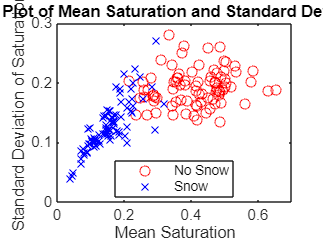


% Save the test table for use in the Classification Learner app
save('testTable.mat', 'testTable');

% Optionally, you can load the table in the Classification Learner app
% by using:
% load('trainingTable.mat');
% load('testTable.mat');
% classificationLearner;

% Create the scatter plot
figure;
gscatter(trainingTable.MeanSaturation, trainingTable.StdSaturation, trainingTable.Label, 'rb', 'ox');
xlabel('Mean Saturation');
ylabel('Standard Deviation of Saturation');
title('Grouped Scatter Plot of Mean Saturation and Standard Deviation of Saturation');
legend('No Snow', 'Snow');

% Save the figure
saveas(gcf, 'GroupedScatterPlot.png');


% Display the result
disp('Scatter plot created and saved as GroupedScatterPlot.png');

Scatter plot created and saved as GroupedScatterPlot.png
